preflood = imread("stlouis_l5tm_14aug91_30m.jpg")

preflood = 3600×3600×3 uint8 array
preflood(:,:,1) =

    99   100   100   103   108   109   105   101   113   112   111   109   108   105   101    99    91    95    98   100   100   104   109   114    89    93    98    98    95    92    92    94    81    92   101   102   100    98    92    83    98    90    95   103   106   123   133   122    97   100    96    87    90   101   103    97   106   100    94    95    99   104   113   122   120   126   137   147   151   146   136   127   145   142   135   122   124   138   139   124    93    91    90    90    94    98    97    96    90    91    93    93    92    88    83    80   133   141   138   118   102   102   114   123   130   126   110    95    92   106   127   139   142   137   136   134   124   107    92    89    80    83   118   137   105    84    89    91   103    98    89    82    81    83    89    92    94    92    95    99    94    85    88    99   102    98   107   129   128   107    90    91    86    91    97    99    95    

postflood = imread("stlouis_l5tm_19aug93_30m.jpg")

postflood = 3600×3600×3 uint8 array
postflood(:,:,1) =

   117    99    92    90    82    90   109   114   136   125   110   101   102   103    99    95    95    89    85    87    91    99   105   107   105   107   106   103    99    98   103   108   102   101    98   100   105   107   107   105   127   134   137   131   120   109   107   107   111   114   116   110   105   106   111   116   135   140   147   149   145   130   109    96   106    95    95   101   100   101    95    79    40    62    82    87    86    87    89    88    92    91    90    91    95    97    92    87    87    84    82    82    86    88    88    86    97    96    96    95    90    93   107   124    94    93   103   114   110    96    97   110   110   127   124   109   108   100    87    85    86    90    89    86    91   103   105    99    94    95    91    87    91    98   100    98    98    93    86    94   103    99   103   121   142   136   128   120   117   120   125   127   132   130   118   103    95  

% these functions are generated by color thresholder app
function [BW,maskedRGBImage] = preFloodMask(RGB)
I = rgb2hsv(RGB);
channel1Min = 0.489;
channel1Max = 0.753;
channel2Min = 0.000;
channel2Max = 1.000;
channel3Min = 0.000;
channel3Max = 1.000;

sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end


function [BW,maskedRGBImage] = postFloodMask(RGB)
I = rgb2hsv(RGB);
channel1Min = 0.505;
channel1Max = 0.818;
channel2Min = 0.000;
channel2Max = 1.000;
channel3Min = 0.000;
channel3Max = 1.000;

sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end

[BWpre, maskpre] = preFloodMask(preflood)

BWpre = 3600×3600 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

maskpre = 3600×3600×3 uint8 array
maskpre(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

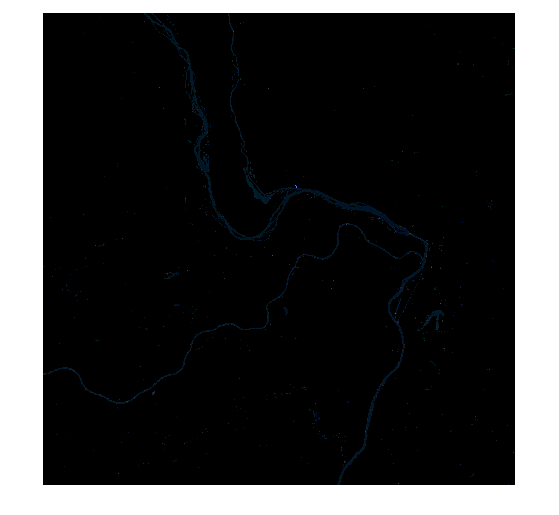

imshow(maskpre)


[BWpost, maskpost] = postFloodMask(postflood)

BWpost = 3600×3600 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

maskpost = 3600×3600×3 uint8 array
maskpost(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

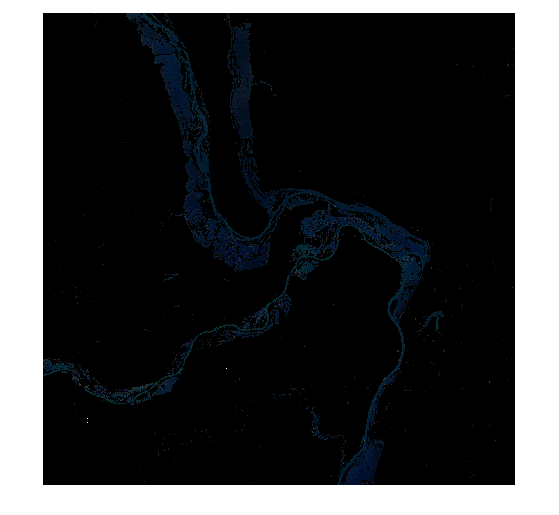

imshow(maskpost)

% numerical analysis to calculate the number of blue river pixels
nnz(BWpre)

ans = 282907

nnz(BWpost)

ans = 1053270

% calculating the water increase percentage
(nnz(BWpost) - nnz(BWpre)) / nnz(BWpre) * 100

ans = 272.3026


% 272 percent is a huge increase in water